remove bTrainingWithValidation ;

train = 80%

validatiion = 15%

test = 5%

use dividerand

clear ;
close all;

load ryan2_gen_data.mat

머신러닝 방법을 사용하기 위해 데이타 정규화.

이때 test set 에서도 동일한 범위로 동작하기 위해 모든 데이타에 대해 한번에 정규화해야 함.

ynorm,xnorm = training set

ytestnorm,xtestnorm = test set

idx = idxAll;
y = [battery_dataset(idx).cycle_life ]';
x = (reshape([battery_dataset(idx).Ic],100,length(y)))';
[ynormall,ymax,ymin,yrate,xnormall,xmax,xmin,xrate] = minmax_norm_all(y,x);


%%% LSTM 회귀
%idx = idxAll; %RMSE = 1032  - 잘 동작
idx = idx12 ; % training set - 
idxtest = idx3 ; % training set - 
%idx = idx1;
key = [battery_dataset(idx).key]';
% s1 = string([{battery_dataset(idx).policy}])
% policy = [{battery_dataset(idx).policy}]';
% policy_str = string([{battery_dataset(idx).policy}]');
% policy_readable = [{battery_dataset(idx).policy_readable}]';
% policy_readable_str = string([{battery_dataset(idx).policy_readable}]');
%Ic1 = [{battery_dataset(idx).Ic}]';
%Ic_ = [battery_dataset(idx).Ic];
%Ic__ = reshape(Ic_,100,length(policy));
%Ic = Ic__';
y = [battery_dataset(idx).cycle_life ]';
x_input_size = 100;
x = (reshape([battery_dataset(idx).Ic],x_input_size,length(y)))';

keytest = [battery_dataset(idxtest).key]';
ytest = [battery_dataset(idxtest).cycle_life ]';
xtest = (reshape([battery_dataset(idxtest).Ic],x_input_size,length(ytest)))';

[ynorm,xnorm] = norm_with(y,x,ymax,ymin,xmax,xmin);
[ytestnorm,xtestnorm] = norm_with(ytest,xtest,ymax,ymin,xmax,xmin);

% xnorm = x;
% ynorm = y;
% Test_Input = xtest;
% Test_Output = ytest;

FNN 으로 테스트 - training set (test/validation 없이 )

feedforwardnet([50,10] => 2개충, 첫번째 50 뉴런, 두번째층 10 개 뉴런

=== 참조 ==

`hiddenSizes` **—** **Size of the hidden layers**

10 (default) | row vector

Size of the hidden layers in the network, specified as a row vector. The length of the vector determines the number of hidden layers in the network.

**Example:** For example, you can specify a network with 3 hidden layers, where the first hidden layer size is 10, the second is 8, and the third is 5 as follows: `[10,8,5]`

The input and output sizes are set to zero. The software adjusts the sizes of these during training according to the training data.

**Data Types:** `single` | `double`

[https://kr.mathworks.com/matlabcentral/answers/260613-validation-sets-vs-test-sets](https://kr.mathworks.com/matlabcentral/answers/260613-validation-sets-vs-test-sets)

`Total     = Design + Nondesign`

` Design    = Training + Validation`

` Nondesign = Testing`

` Total       = Training + Nontraining`

` Nontraining = Validation + Testing`

` Overfitting: Using more ``weights and biases than necessary`

` Overtraining: Improving the ``performance of the training data at the expense of deteriorating the performance`

` on ``nontraining data`

` Training ``data subset: Used to DIRECTLY estimate weights and biases. Performance estimates are BIASED.`

` Validation ``data subset: Used to `

` (1) determine ``when overtraining an overfit net begins to occur AND `

` (2) rank ``multiple designs. `

` Performance ``estimates are SIGNIFICANTLY LESS BIASED than training data estimates.`

` Test data subset: Used to obtain UNBIASED ESTIMATES of performance on nontraining (INCLUDING UNSEEN!) data`

[https://kr.mathworks.com/help/deeplearning/ref/dividerand.html](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html)

`[`[`trainInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_1728d793-edc6-4595-8a0d-22992dffe813)`,`[`valInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_caf766f1-5912-45f0-919e-f903b9d313f4)`,`[`testInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_8e6cbc0b-a46a-4dbf-b95c-5eb6fcd46e9b)`] = dividerand(`[`Q`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_a6062bcf-a3b1-4224-9caa-fa872fae85d3)`,`[`trainRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_72c9b34e-a329-46f2-a907-39b169c6e19a)`,`[`valRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_2abef95f-2bd8-4aec-8a09-126cd5c93bcc)`,`[`testRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_f4192d38-e08b-446c-af8a-ee0cc9472af8)`)`는 나눌 목표값의 개수, 훈련에 사용할 벡터의 비율, 검증에 사용할 벡터의 비율, 테스트에 사용할 벡터의 비율을 받고, 훈련 인덱스, 검증 인덱스, 테스트 인덱스를 반환합니다

[https://kr.mathworks.com/help/deeplearning/ug/divide-data-for-optimal-neural-network-training.html](https://kr.mathworks.com/help/deeplearning/ug/divide-data-for-optimal-neural-network-training.html)

훈련, 테스트 및 검증의 디폴트 비율은 각각 0.7, 0.15, 0.15입니다.

[https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html](https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html)

베이즈 정규화는 함수 [`trainbr`](https://kr.mathworks.com/help/deeplearning/ref/trainbr.html)에 구현되어 있습니다. 다음 코드는 이 함수를 사용하여 1-20-1 신경망이 [얕은 신경망 일반화를 개선하고 과적합 방지하기](https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html) 항목의 그림에 나와 있는 잡음이 있는 사인파를 근사하도록 훈련시키는 방법을 보여줍니다. ([`trainbr`](https://kr.mathworks.com/help/deeplearning/ref/trainbr.html)의 영향이 조기 중지로부터 격리되도록 `net.divideFcn`을 설정하여 데이터 분할이 취소되었습니다.)

`x = -1:0.05:1;`

`t = sin(2*pi*x) + 0.1*randn(size(x));`

`net = feedforwardnet(20,'trainbr');`

`net = train(net,x,t);`

- FNN with 10 hidden neurons.

%https://kr.mathworks.com/help/deeplearning/ref/dividerand.html
trainRatio = 0.80;
valRatio = 0.15;
testRatio = 0.05;
xnorm_count = size(xnorm,1)

xnorm_count = 79

[trainInd,valInd,testInd] = dividerand(xnorm_count,trainRatio,valRatio,testRatio);

netFNN1_v2 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_v2.divideFcn 

ans = 'dividerand'

netFNN1_v2.divideParam

ans =  
    Function Parameters for 'dividerand'
 
    Training Ratio trainRatio: 0.7
    Validation Ratio valRatio: 0.15
    Test Ratio      testRatio: 0.15
 

netFNN1_v2.divideMode

ans = 'sample'

% dividerand 는 아래의 문제가 있음. 재현시마다 다른 결과 .
%https://kr.mathworks.com/matlabcentral/answers/22100-neural-network-reproducibility-of-results-using-neural-networks-without-initfcn-rands

netFNN1_v2.divideFcn = 'dividerand';
netFNN1_v2.divideParam.trainRatio = trainRatio;
netFNN1_v2.divideParam.valRatio = valRatio;
netFNN1_v2.divideParam.testRatio = testRatio; 
netFNN1_v2.divideParam

ans =  
    Function Parameters for 'dividerand'
 
    Training Ratio trainRatio: 0.8
    Validation Ratio valRatio: 0.15
    Test Ratio      testRatio: 0.05
 


netFNN1_v2.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_v2, tr] = train(netFNN1_v2, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


tr

tr = struct with fields:
        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1 2 3 4 6 7 8 9 11 12 13 14 15 16 17 18 19 20 21 24 26 27 28 30 32 33 34 35 36 37 38 39 40 42 43 44 45 46 48 49 50 51 52 53 54 55 56 57 58 59 60 62 63 65 66 67 68 70 72 74 75 76 77]
          valInd: [10 23 25 29 41 47 61 64 71 73 78 79]
         testInd: [5 22 31 69]
            stop: 'Validation stop.'
      num_epochs: 10
       trainMask: {[1 1 1 1 NaN 1 1 1 1 NaN 1 1 1 1 1 1 1 1 1 1 1 NaN NaN 1 NaN 1 1 1 NaN 1 NaN 1 1 1 1 1 1 1 1 1 NaN 1 1 1 1 1 NaN 1 1 1 1 1 1 1 1 1 1 1 1 1 NaN 1 1 NaN 1 1 1 1 NaN 1 NaN 1 NaN 1 1 1 1 NaN NaN]}
         valMask: {[1×79 double]}
        testMask: {[1×79 double]}
      best_epoch: 4
            goal: 0
          states: {'epoch'  'time'  'perf'  'vperf'  'tperf'  'mu'  'grad


netFNN2_v2 = feedforwardnet([50,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
%netFNN2_v2
%netFNN2_v2.divideParam

% dividerand 의 경우 동일한 항목으로 train하지 않는다.
% netFNN2_v2.divideFcn = 'dividerand';
% netFNN2_v2.divideParam.trainRatio = trainRatio;
% netFNN2_v2.divideParam.valRatio = valRatio;
% netFNN2_v2.divideParam.testRatio = testRatio; 
% netFNN2_v2.divideParam
netFNN2_v2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_v2.divideParam.trainInd = tr.trainInd;
netFNN2_v2.divideParam.valInd = tr.valInd;
netFNN2_v2.divideParam.testInd = tr.testInd; 

netFNN2_v2.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_v2.trainParam.show = NaN;
[netFNN2_v2, tr2] = train(netFNN2_v2, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN2_v2)
netFNN2_v2

netFNN2_v2 =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 5521
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      

tr2

tr2 = struct with fields:
        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'divideind'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1 2 3 4 6 7 8 9 11 12 13 14 15 16 17 18 19 20 21 24 26 27 28 30 32 33 34 35 36 37 38 39 40 42 43 44 45 46 48 49 50 51 52 53 54 55 56 57 58 59 60 62 63 65 66 67 68 70 72 74 75 76 77]
          valInd: [10 23 25 29 41 47 61 64 71 73 78 79]
         testInd: [5 22 31 69]
            stop: 'Validation stop.'
      num_epochs: 7
       trainMask: {[1 1 1 1 NaN 1 1 1 1 NaN 1 1 1 1 1 1 1 1 1 1 1 NaN NaN 1 NaN 1 1 1 NaN 1 NaN 1 1 1 1 1 1 1 1 1 NaN 1 1 1 1 1 NaN 1 1 1 1 1 1 1 1 1 1 1 1 1 NaN 1 1 NaN 1 1 1 1 NaN 1 NaN 1 NaN 1 1 1 1 NaN NaN]}
         valMask: {[1×79 double]}
        testMask: {[1×79 double]}
      best_epoch: 1
            goal: 0
          states: {'epoch'  'time'  'perf'  'vperf'  'tperf'  'mu'  'gradi

netFNN3_v2 = feedforwardnet([100,50,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_v2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN3_v2.divideParam.trainInd = tr.trainInd;
netFNN3_v2.divideParam.valInd = tr.valInd;
netFNN3_v2.divideParam.testInd = tr.testInd; 

netFNN3_v2.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_v2.trainParam.show = NaN;
netFNN3_v2 = train(netFNN3_v2, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN3_v2)

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:07 |         0.32 |      5.1e-02 |          0.0010 |
|      50 |          50 |       00:00:10 |         0.08 |      3.6e-03 |          0.0010 |
|     100 |         100 |       00:00:15 |         0.07 |      2.5e-03 |          0.0010 |
|     150 |         150 |       00:00:33 |         0.06 |      2.0e-03 |          0.0010 |
|     200 |         200 |       00:00:40 |         0.06 |      1.6e-03 |          0.0010 |
|     250 |         250 |       00:00:43 |         0.05 |      1.3e-03 |          0.0010 |
|     300 |         300 |  

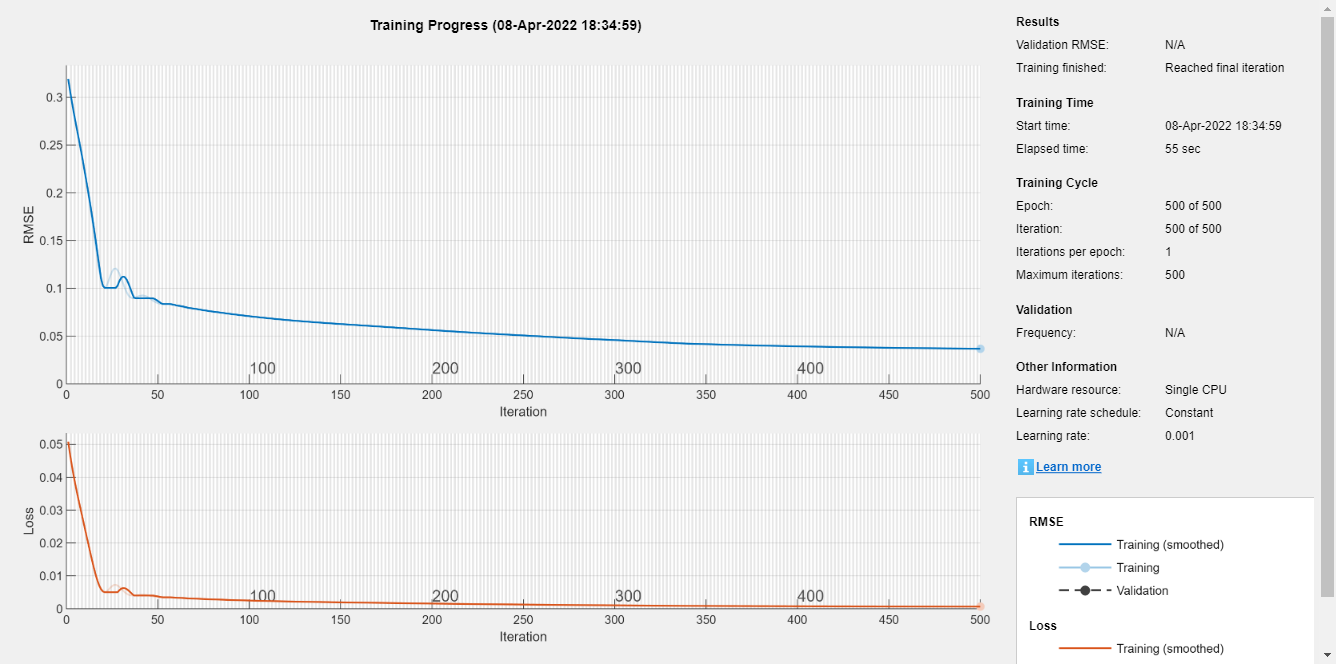

input_size = 100;
layerCNN1 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(xnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',500, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);
 netCNN1_v2 = trainNetwork(Traintbl, layerCNN1, options);



%


- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |         0.35 |      6.1e-02 |          0.0010 |
|      50 |          50 |       00:00:07 |         0.09 |      3.9e-03 |          0.0010 |
|     100 |         100 |       00:00:07 |         0.08 |      2.9e-03 |          0.0010 |
|     150 |         150 |       00:00:08 |         0.07 |      2.1e-03 |          0.0010 |
|     200 |         200 |       00:00:09 |         0.06 |      1.7e-03 |          0.0010 |
|     250 |         250 |       00:00:10 |         0.05 |      1.5e-03 |          0.0010 |
|     300 |         300 |  

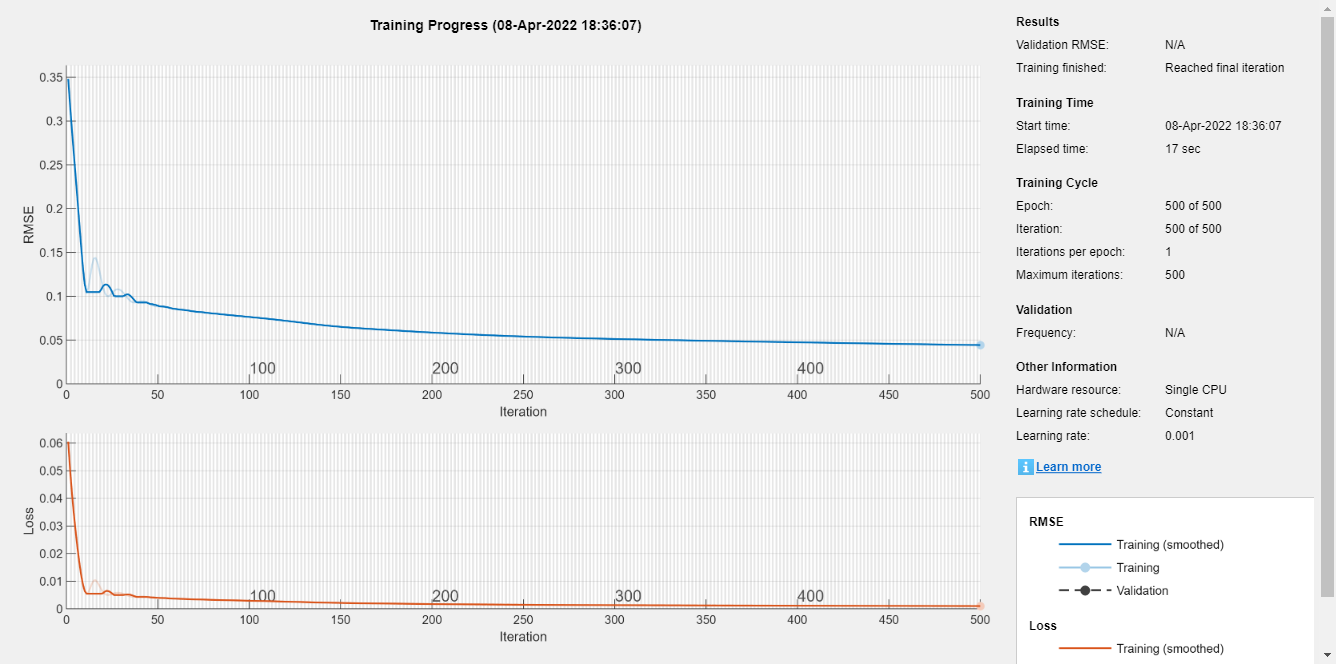

layerCNN2 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2], 30, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 15, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];

netCNN2_v2 = trainNetwork(Traintbl, layerCNN2, options);


- LSTM : 1 lstm layer with 5 hidden units

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |         0.38 |      7.3e-02 |          0.0010 |
|      50 |          50 |       00:00:07 |         0.09 |      4.0e-03 |          0.0010 |
|     100 |         100 |       00:00:08 |         0.08 |      2.8e-03 |          0.0010 |
|     150 |         150 |       00:00:09 |         0.06 |      2.1e-03 |          0.0010 |
|     200 |         200 |       00:00:10 |         0.06 |      1.8e-03 |          0.0010 |
|     250 |         250 |       00:00:12 |         0.06 |      1.6e-03 |          0.0010 |
|     300 |         300 |       00:00:13 |         0.06 |      1.5

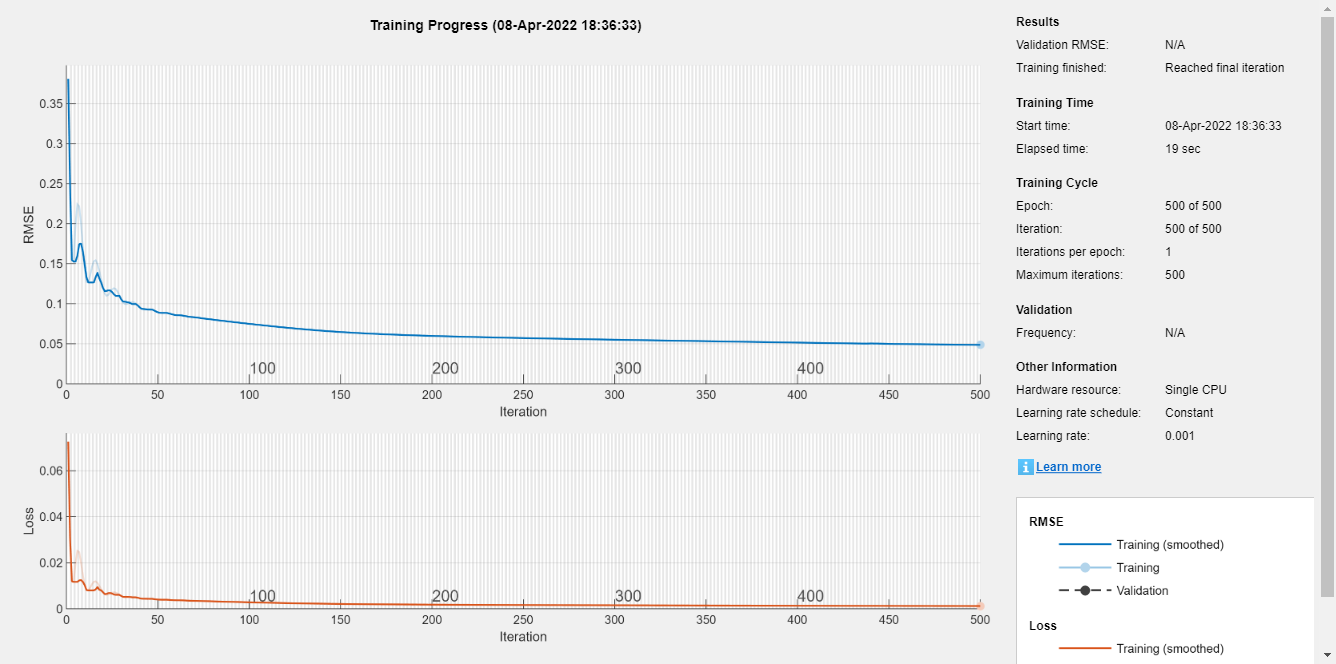

numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm', 1)';
cellyB = num2cell(ynorm);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
     'InitialLearnRate', 0.001, ...
     'MaxEpochs',500, ...
     'MiniBatchSize',50, ...
     'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

    netLSTM_v2 = trainNetwork(traincellx, traincellyB, layersLSTM, options);



%ryan2_gen_data_model_desc = 'ryan2_gen_data_model';
%save('ryan2_gen_data_model.mat','ryan2_gen_data_model_desc');
save('ryan2_gen_data_model.mat','netFNN1_v2' ,'-append')
save('ryan2_gen_data_model.mat','netFNN2_v2' ,'-append')
save('ryan2_gen_data_model.mat','netFNN3_v2' ,'-append')
save('ryan2_gen_data_model.mat','netCNN1_v2' ,'-append')
save('ryan2_gen_data_model.mat','netCNN2_v2' ,'-append')
save('ryan2_gen_data_model.mat','netLSTM_v2' ,'-append')


if bTrainingWithValidation

### Prediciton using each 5 trained model

Make a prediction **using trained models**

- FNN1

pFNN1 = netFNN1_v2(xnorm(tr.testInd, :)');

- FNN40

pFNN = netFNN2_v2(xnorm(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(xnorm(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1_v2, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2_v2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM_v2, num2cell(xnorm(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

y_real = ynorm(tr.testInd, :)*yrate + ymin;
pFNN1_hat = pFNN1*yrate+ ymin;
pFNN_hat = pFNN*yrate + ymin;
pCNN1_hat = pCNN1*yrate + ymin;
pCNN2_hat = pCNN2*yrate + ymin;
pLSTM_hat = pLSTM*yrate + ymin;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

figure, hold on, grid on,
plot(y_real, 'linewidth', 2), plot(pFNN1_hat, '*--'), plot(pFNN_hat, '^--'), plot(pCNN1_hat, 'o--'), plot(pCNN2_hat, 'x--'), plot(pLSTM_hat, '-.')
%plot(1:25, 1.4*ones(1, 25),'k--','LineWidth', 2), xlim([1 25])
%title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cell
ylabel 'Cycle life'
legend('Real Value', 'FNN1 Predicted', 'FNN Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted')

RMSE

rmse_pFNN1 = sqrt(mean(( y_real' - pFNN1_hat ).^2))
rmse_pFNN = sqrt(mean(( y_real' - pFNN_hat ).^2))
rmse_pCNN1  = sqrt(mean(( y_real' - pCNN1_hat' ).^2))
rmse_pCNN2  = sqrt(mean(( y_real' - pCNN2_hat' ).^2))
rmse_pLSTM  = sqrt(mean(( y_real' - pLSTM_hat' ).^2))
end

ytestnorm_hat_netFNN1 = netFNN1_v2(xtestnorm');
ytestnorm_hat_netFNN2 = netFNN2_v2(xtestnorm');
ytestnorm_hat_netFNN3 = netFNN3_v2(xtestnorm');

total_cycle = length(ytestnorm_hat_netFNN);
cellx = num2cell(xtestnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, x_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
ytestnorm_hat_netCNN1 = predict(netCNN1_v2, x_4d);
ytestnorm_hat_netCNN2 = predict(netCNN2_v2, x_4d);
ytestnorm_hat_netLSTM = cell2mat(predict(netLSTM_v2, num2cell(xtestnorm', 1)));

ytest_real = ytestnorm*yrate + ymin;
ytest_hat_netFNN1 = ytestnorm_hat_netFNN1*yrate + ymin;
ytest_hat_netFNN2 = ytestnorm_hat_netFNN2*yrate + ymin;
ytest_hat_netFNN3 = ytestnorm_hat_netFNN3*yrate + ymin;
ytest_hat_netCNN1 = ytestnorm_hat_netCNN1*yrate + ymin;
ytest_hat_netCNN2 = ytestnorm_hat_netCNN2*yrate + ymin;
ytest_hat_netLSTM = ytestnorm_hat_netLSTM*yrate + ymin;



RMSE

rmse_ytest_hat_netFNN1 = sqrt(mean(( ytest_real' - ytest_hat_netFNN1 ).^2))

rmse_ytest_hat_netFNN1 = 460.3747

rmse_ytest_hat_netFNN2 = sqrt(mean(( ytest_real' - ytest_hat_netFNN2 ).^2))

rmse_ytest_hat_netFNN2 = 534.5424

rmse_ytest_hat_netFNN3 = sqrt(mean(( ytest_real' - ytest_hat_netFNN3 ).^2))

rmse_ytest_hat_netFNN3 = 512.8715

rmse_ytest_hat_netCNN1 = sqrt(mean(( ytest_real' - ytest_hat_netCNN1' ).^2))

rmse_ytest_hat_netCNN1 = single
589.0970

rmse_ytest_hat_netCNN2  = sqrt(mean(( ytest_real' - ytest_hat_netCNN2' ).^2))

rmse_ytest_hat_netCNN2 = single
482.3940

rmse_ytest_hat_netLSTM  = sqrt(mean(( ytest_real' - ytest_hat_netLSTM' ).^2))

rmse_ytest_hat_netLSTM = single
533.5958

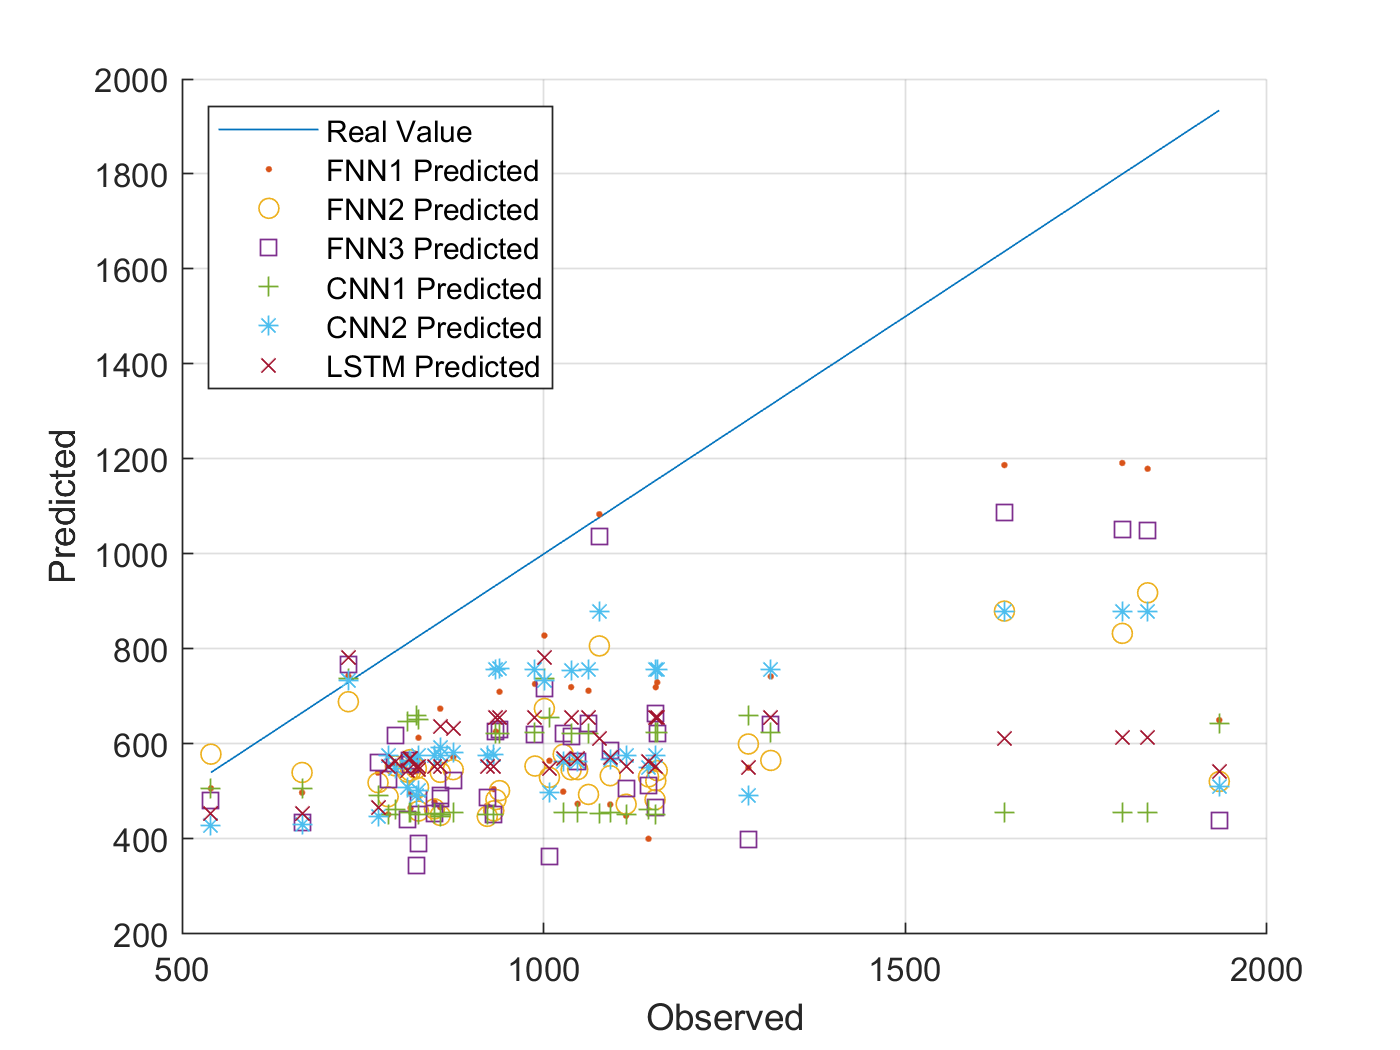


ytest = ytestnorm*yrate + ymin;

figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,ytest_hat_netFNN1,'.')
plot(ytest,ytest_hat_netFNN2,'o')
plot(ytest,ytest_hat_netFNN3,'s')
plot(ytest,ytest_hat_netCNN1,'+')
plot(ytest,ytest_hat_netCNN2,'*')
plot(ytest,ytest_hat_netLSTM,'x')
hold off
xlabel Observed
ylabel Predicted
legend({'Real Value', 'FNN1 Predicted', 'FNN2 Predicted', 'FNN3 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted'},'Location','northwest')

%%여기까지

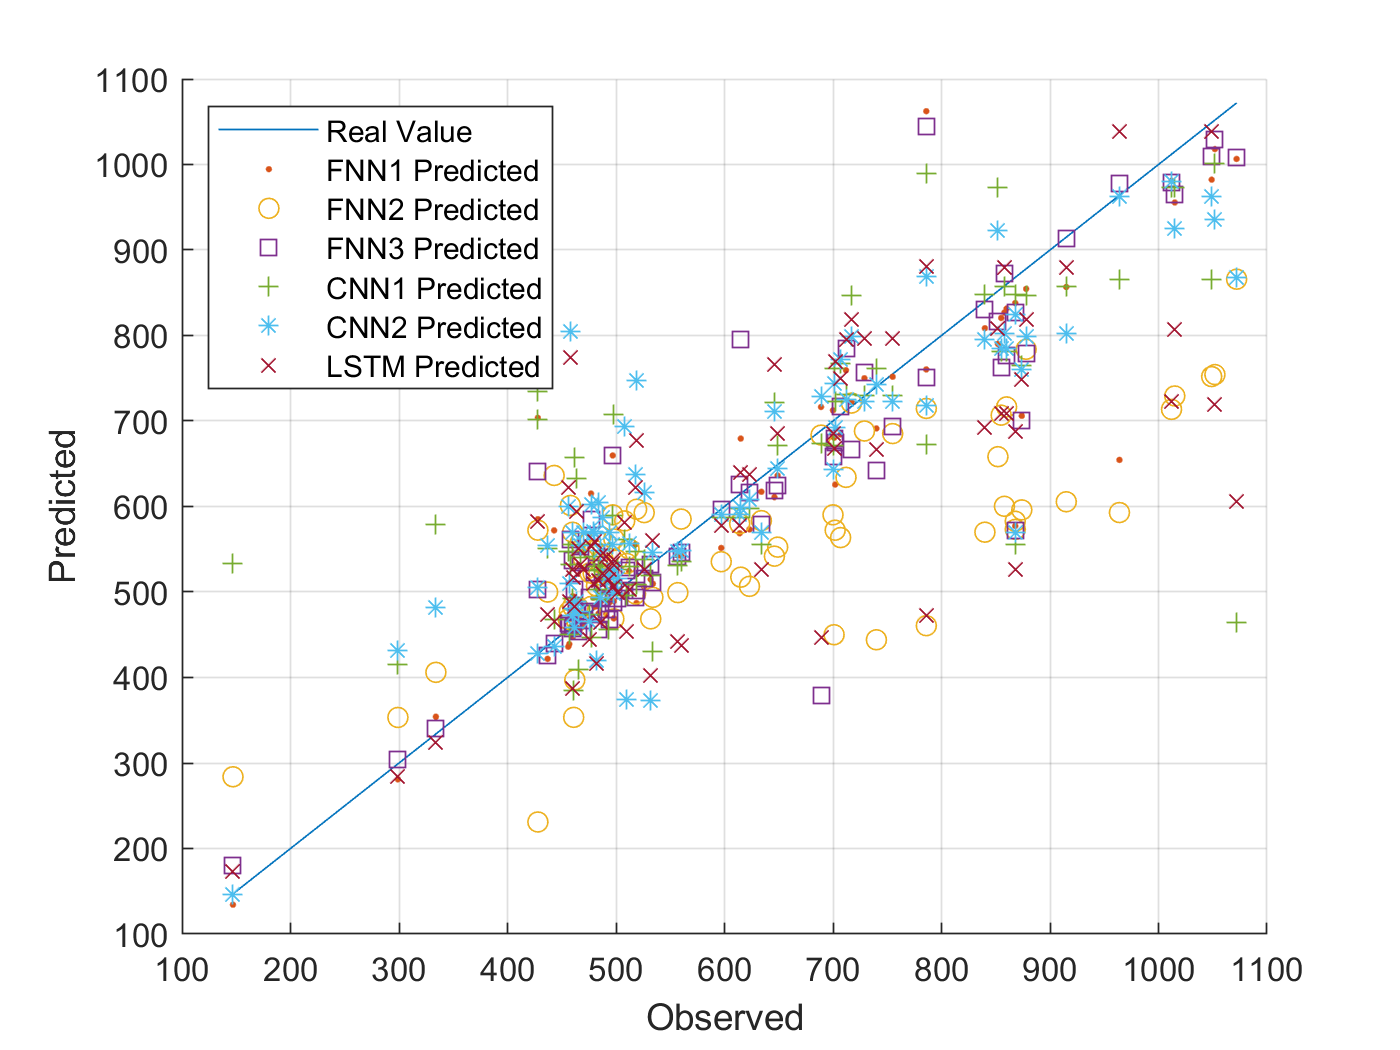


%%%%%%%%%%%% 학습한 데이타로 검증
ynorm_hat_netFNN1_self = netFNN1_v2(xnorm');
ynorm_hat_netFNN2_self = netFNN2_v2(xnorm');
ynorm_hat_netFNN3_self = netFNN3_v2(xnorm');

total_cycle = length(ytestnorm_hat_netFNN);
cellx = num2cell(xnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, x_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

ynorm_hat_netCNN1_self = predict(netCNN1_v2, x_4d);
ynorm_hat_netCNN2_self = predict(netCNN2_v2, x_4d);
ynorm_hat_netLSTM_self = cell2mat(predict(netLSTM_v2, num2cell(xnorm', 1)));


y_self = ynorm*yrate + ymin;

y_hat_netFNN1_self = ynorm_hat_netFNN1_self * yrate + ymin;
y_hat_netFNN2_self = ynorm_hat_netFNN2_self * yrate + ymin;
y_hat_netFNN3_self = ynorm_hat_netFNN3_self * yrate + ymin;
y_hat_netCNN1_self = ynorm_hat_netCNN1_self * yrate + ymin;
y_hat_netCNN2_self = ynorm_hat_netCNN2_self * yrate + ymin;
y_hat_netLSTM_self = ynorm_hat_netLSTM_self * yrate + ymin;


figure, hold on, grid on,
plot(y_self,y)
plot(y_self,y_hat_netFNN1_self,'.')
plot(y_self,y_hat_netFNN2_self,'o')
plot(y_self,y_hat_netFNN3_self,'s')
plot(y_self,y_hat_netCNN1_self,'+')
plot(y_self,y_hat_netCNN2_self,'*')
plot(y_self,y_hat_netLSTM_self,'x')
hold off
xlabel Observed
ylabel Predicted
legend({'Real Value', 'FNN1 Predicted', 'FNN2 Predicted', 'FNN3 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted'},'Location','northwest')


rmse_y_hat_netFNN1_self  = sqrt(mean(( y_self' - y_hat_netFNN1_self  ).^2))

rmse_y_hat_netFNN1_self = 81.0043

rmse_y_hat_netFNN2_self  = sqrt(mean(( y_self' - y_hat_netFNN2_self  ).^2))

rmse_y_hat_netFNN2_self = 147.9312

rmse_y_hat_netFNN3_self  = sqrt(mean(( y_self' - y_hat_netFNN3_self  ).^2))

rmse_y_hat_netFNN3_self = 80.1489

rmse_y_hat_netCNN1_self  = sqrt(mean(( y_self' - y_hat_netCNN1_self' ).^2))

rmse_y_hat_netCNN1_self = single
126.2821

rmse_y_hat_netCNN2_self  = sqrt(mean(( y_self' - y_hat_netCNN2_self' ).^2))

rmse_y_hat_netCNN2_self = single
95.4990

rmse_y_hat_netLSTM_self  = sqrt(mean(( y_self' - y_hat_netLSTM_self' ).^2))

rmse_y_hat_netLSTM_self = single
131.5858

CNN을 위해 충전전류를 2차원 이미지로 만들기

ynormall,ymax,ymin,yrate,xnormall,xmax,xmin,xrate

%{
a = xtestnorm(1,:)

a =          0    0.6248    0.6248    0.6245    0.6245    0.6246    0.6245    0.6245    0.6246    0.6245    0.6245    0.6245    0.6245    0.6245    0.6245    0.6245    0.6246    0.6245    0.6246    0.6245    0.6246    0.6245    0.6245    0.6244    0.6245    0.6245    0.6245    0.6245    0.6244    0.6245    0.6245    0.6245    0.6245    0.6245    0.6245    0.6244    0.6246    0.6245    0.6245    0.6244    0.6245    0.6244    0.6244    0.6244    0.6245    0.6244    0.6244    0.6244    0.6243    0.6243


b = zeros(100,100);
c = round(xtestnorm(1,:)* 100)

c =      0    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62    62


for i=1:100
    b(i,c(i)+1)=1;
end
b

b =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


xxx = [1:100]

xxx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



space = [ 1:100]

space =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


new_space = [1:28]

new_space =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28


new_xxx = interp1(space,xxx,new_space,'linear')

new_xxx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28


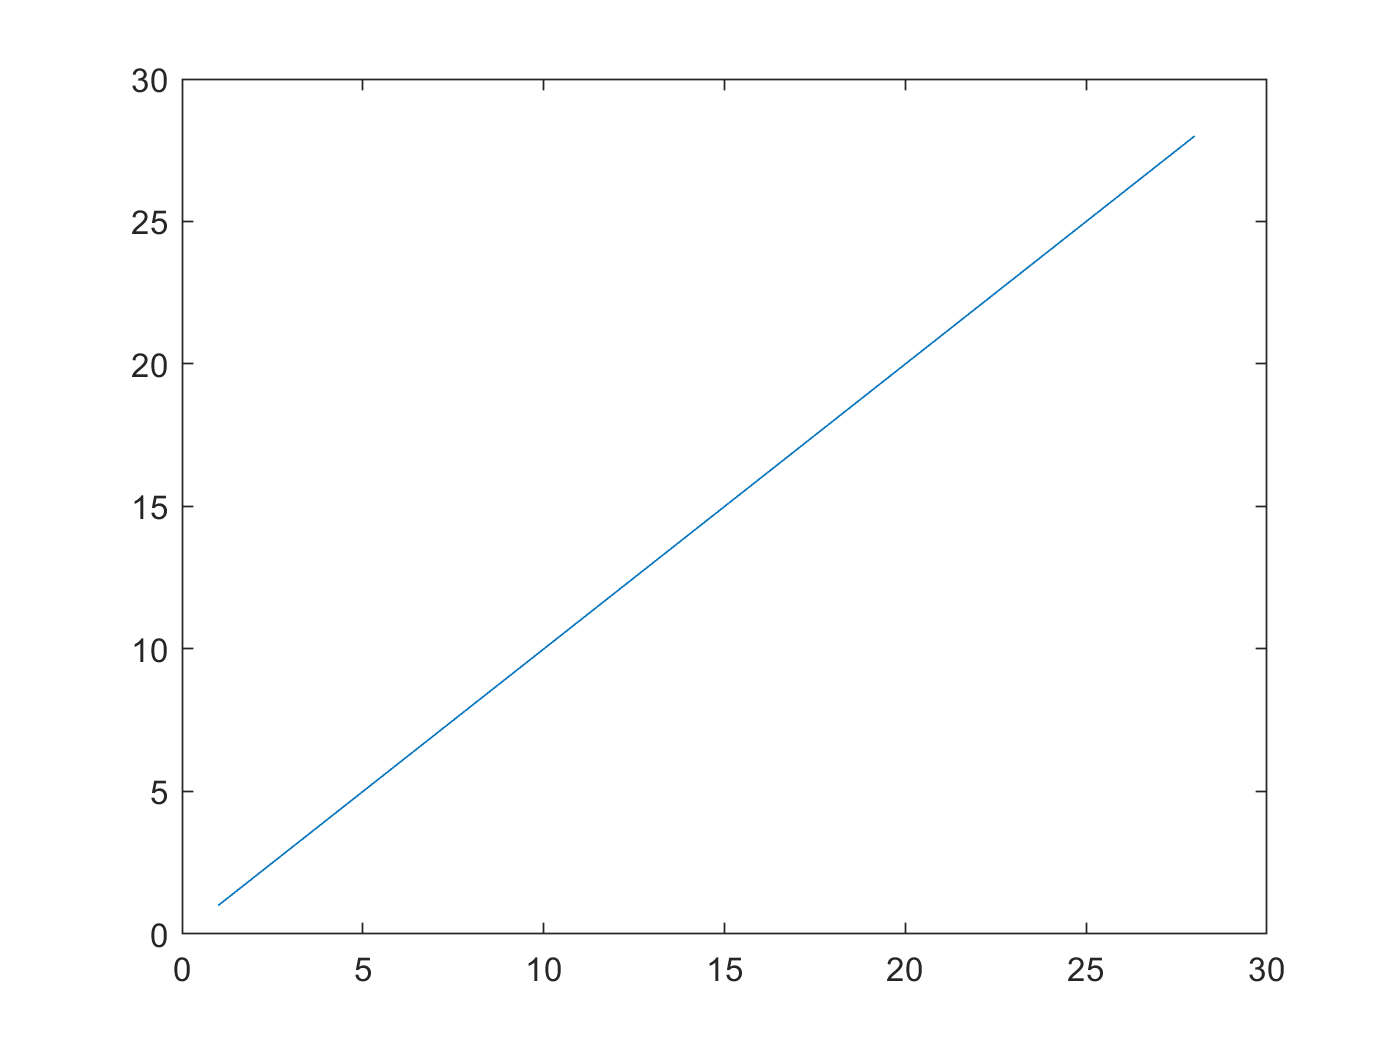

figure
plot(new_xxx)


plot_max_x = 28;
plot_max_y = 28 ;

%a = 
%x = 
xx_max = 28
y_max = 28
rows = max(xtestnorm(1,:));
columns = length(yo);
outputImage = false(rows, columns);
for k = 1 : columns
  outputImage(yo(k), k) = true;
end
imshow(outputImage);
%}